# Lab Activity 

#### ### Agam Goyal ###

### fMRI reference waveform

This waveform is used to identify the period of the task so that other pixels associated with the task may be identified.

## Prepare Workspace

clear
close all

% load 122 x 1 reference signal waveform 
load fmrisig.mat

## Item 6 (i): Plot reference signal 

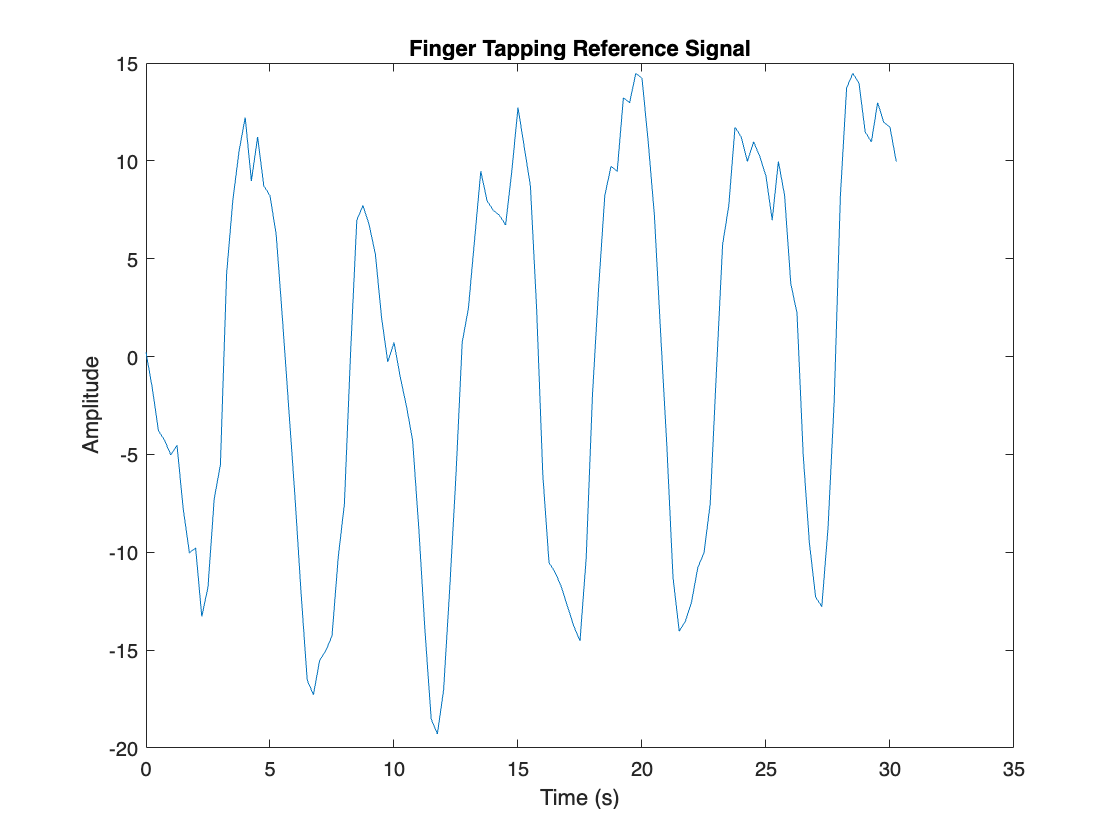

N = length(s);
fs = 4;
t = (0:N-1)/fs;

figure
plot(t,s)
title('Finger Tapping Reference Signal')
ylabel('Amplitude')
xlabel('Time (s)')

## Item 6 (ii): Plot Spectrum

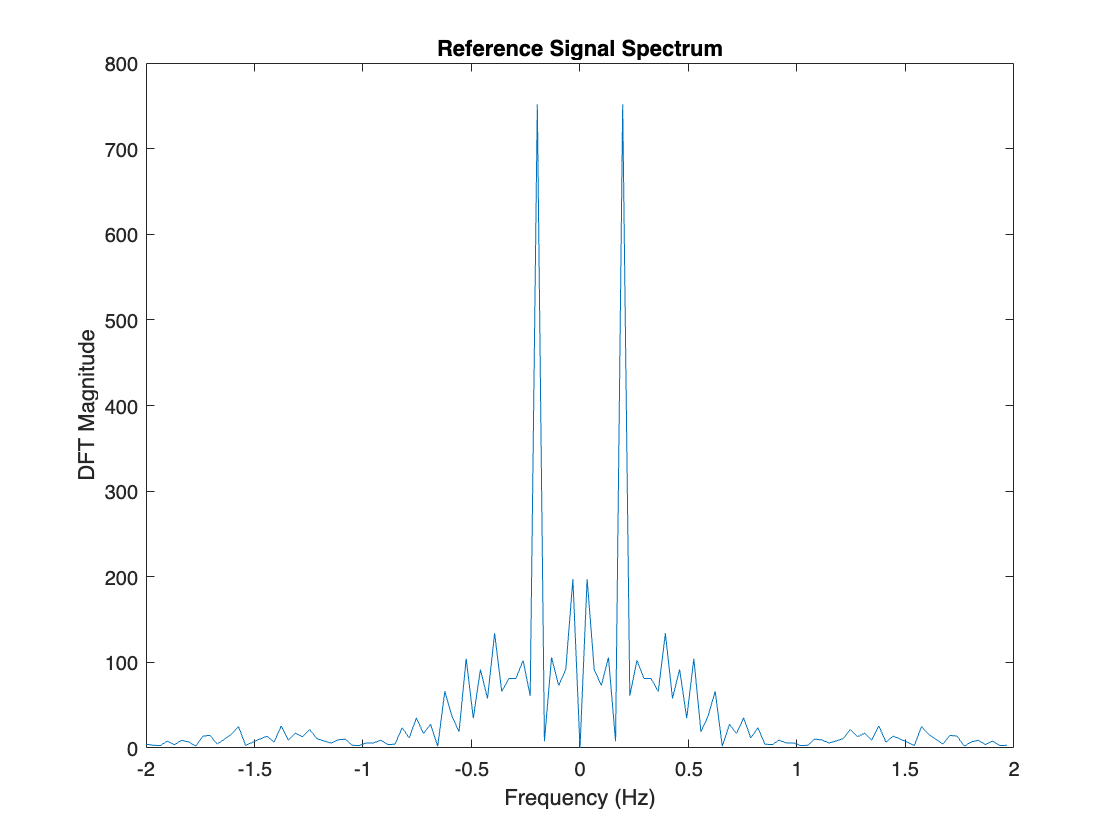

% Plot magnitude of DFT of reference

f_hz = (-N/2:(N/2)-1)*fs/N;
S = fft(s); % Compute fft of time signal
S_shift = fftshift(S); % Shift zero-frequency component to center of spectrum


figure
plot(f_hz, abs(S_shift))
title('Reference Signal Spectrum')
xlabel('Frequency (Hz)')
ylabel('DFT Magnitude')


% Write code to find the index of Vector S corresponding to dominant
% positive frequency
    % Hint 1: look up the max function - it may be useful.
    % Hint 2: Question is asking the index for vector S but we are plotting
    % magnitude for S_Shift
index = 0;
max = 0;
for i = 1:N
    if abs(fftshift(S(i))) > max
        max = abs(fftshift(S(i)));
        index = i;
    end
end

index

index = 7

## Item 7: Generate sinusoid approximation

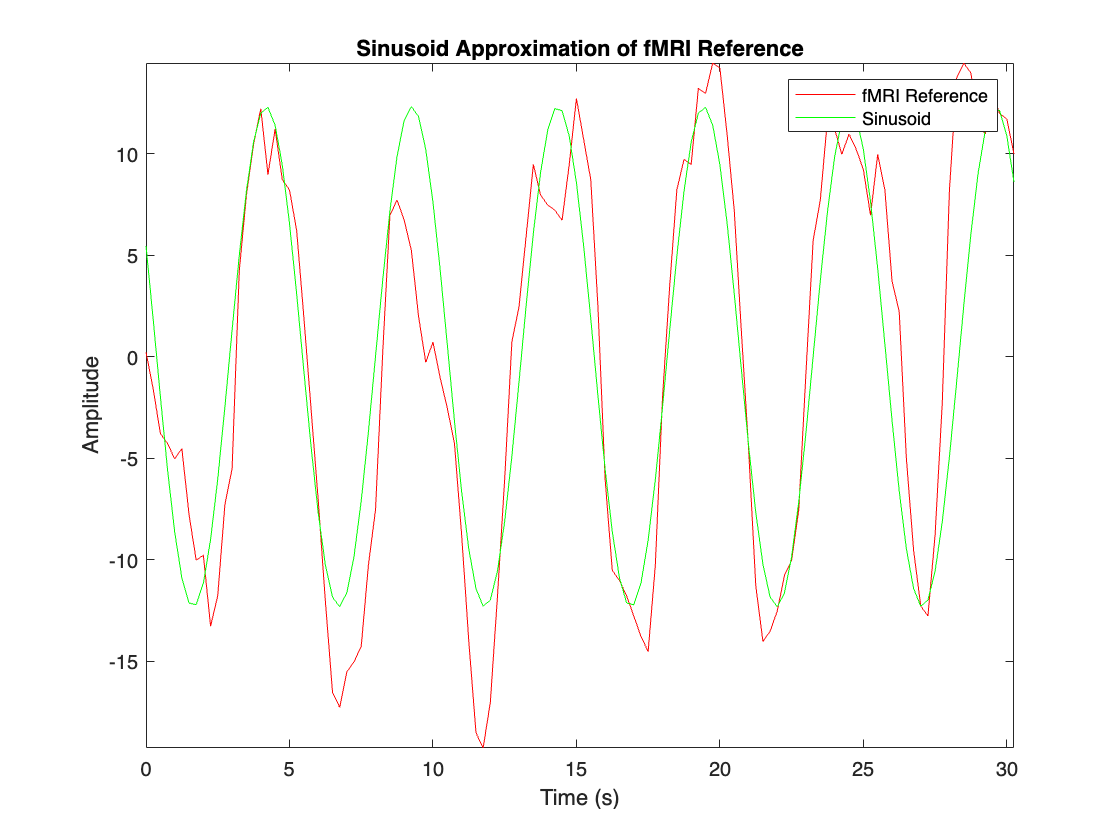

% Complete the following lines of Code and Uncomment to Run
f = 0.1967;
A = 12.3267;
phi = 1.1114;

s_hat = A*cos(2*pi*f*t+phi);

figure
plot(t,s,'r',t,s_hat,'g')
legend('fMRI Reference','Sinusoid')
xlabel('Time (s)')
ylabel('Amplitude')
title('Sinusoid Approximation of fMRI Reference')
axis('tight')